% AI Acknowledgment: Gemini was used to help structure this MATLAB code, 
% identify appropriate functions (such as fitlm and anova1) and provide 
% guidance on interpreting the statistical outputs for the summary.

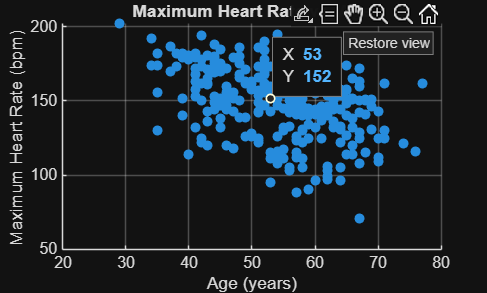

%% Task 1 : Data Exploration and Visualization
% 1. Import the data
data = readtable('Heart_Disease_Dataset.csv');
Age = data.Age;
MaxHeartRate = data.MaxHeartRate;

% 2. Create a scatter plot
figure;
scatter(Age, MaxHeartRate, 'filled');
xlabel('Age (years)');
ylabel('Maximum Heart Rate (bpm)');
title('Maximum Heart Rate vs. Age');
grid on;


% 3. Calculate correlation coefficient (r)
[R, P] = corrcoef(Age, MaxHeartRate);
r_value = R(1,2);
disp(['Correlation coefficient (r): ', num2str(r_value)]);

Correlation coefficient (r): -0.39852


% The correlation coefficient indicates the strength and direction of the linear relationship. 
% A negative value (which is expected here) indicates an inverse relationship: as age increases, the maximum heart rate tends to decrease.

%%Task 2
% 1. Fit simple linear regression model
mdl = fitlm(Age, MaxHeartRate);
disp(mdl);


Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     204.29      7.3485       27.8    3.9808e-85
    x1             -1.0051     0.13332    -7.5386    5.6281e-13


Number of observations: 303, Error degrees of freedom: 301
Root Mean Squared Error: 21
R-squared: 0.159,  Adjusted R-Squared: 0.156
F-statistic vs. constant model: 56.8, p-value = 5.63e-13



% 2. Determine estimated regression equation
b0 = mdl.Coefficients.Estimate(1); % Intercept
b1 = mdl.Coefficients.Estimate(2); % Slope
disp(['Estimated Regression Equation: MaxHeartRate = ', num2str(b0), ' + (', num2str(b1), ') * Age']);

Estimated Regression Equation: MaxHeartRate = 204.2892 + (-1.0051) * Age


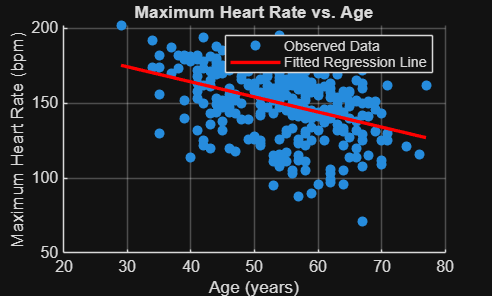


% 3. Add fitted regression line to the scatter plot
hold on;
plot(Age, mdl.Fitted, 'r-', 'LineWidth', 2);
legend('Observed Data', 'Fitted Regression Line');
grid on;
hold off;

%%Task 3
% 1. Find 95% confidence intervals for slope and intercept
ci = coefCI(mdl, 0.05);
disp('95% Confidence Intervals [Intercept; Slope]:');

95% Confidence Intervals [Intercept; Slope]:


disp(ci);

  189.8284  218.7501
   -1.2674   -0.7427




% 2. Hypothesis test for the slope (H0: b1 = 0) at alpha = 0.05
p_value_slope = mdl.Coefficients.pValue(2);
disp(['P-value for the slope: ', num2str(p_value_slope)]);

P-value for the slope: 5.6281e-13


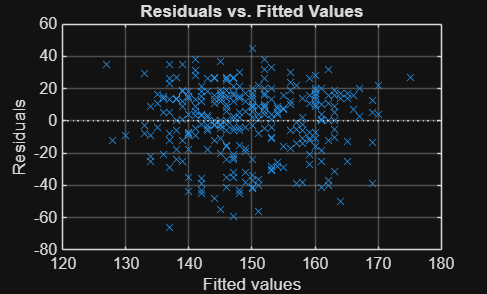

% Since the p-value is compared against our significance level (alpha = 0.05), a p-value < 0.05 means we reject the null hypothesis. This indicates that age is a statistically significant predictor of maximum heart rate.

% 3 . Calculate and plot residuals (Residuals vs. Fitted Values)
figure;
plotResiduals(mdl, 'fitted');
title('Residuals vs. Fitted Values');
grid on;

%%Task 4
% 1. Predict expected max heart rate for 40 and 65 year olds
new_ages = [40; 65];
predicted_HR = predict(mdl, new_ages);
disp(['Predicted Max Heart Rate for Age 40: ', num2str(predicted_HR(1)), ' bpm']);

Predicted Max Heart Rate for Age 40: 164.0861 bpm


disp(['Predicted Max Heart Rate for Age 65: ', num2str(predicted_HR(2)), ' bpm']);

Predicted Max Heart Rate for Age 65: 138.9592 bpm


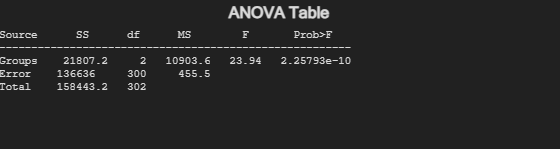

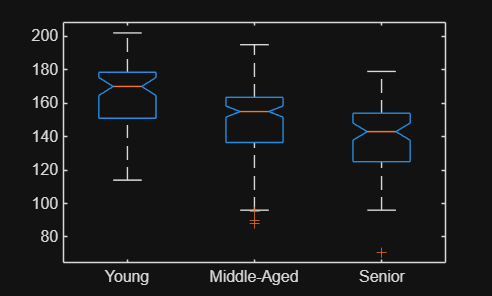


% 2. Perform one-way ANOVA
% First, categorize the data into the three specific groups
age_group = categorical(NaN(size(Age))); 
age_group(Age >= 29 & Age <= 45) = 'Young';      % Group 1 [cite: 34]
age_group(Age >= 46 & Age <= 60) = 'Middle-Aged'; % Group 2 [cite: 35]
age_group(Age >= 61 & Age <= 77) = 'Senior';      % Group 3 [cite: 36]

% Remove any data points that fall outside these specific ranges to clean the ANOVA input
valid_idx = ~isundefined(age_group);
valid_HR = MaxHeartRate(valid_idx);
valid_groups = age_group(valid_idx);

% Run the ANOVA
[p_anova, tbl, stats] = anova1(valid_HR, valid_groups);

disp(['ANOVA p-value: ', num2str(p_anova)]);

ANOVA p-value: 2.2579e-10



% Purpose of ANOVA[cite: 37]:
% While linear regression treats Age as a continuous predictor, ANOVA is used here to test if there is a statistically significant difference in the *mean* maximum heart rate across distinct, categorical age groups (Young, Middle-Aged, and Senior).


Yes, there is a significant linear relationship between age and max heart rate. This is confirmed by the correlation coefficient and the p-value for the regression slope, which falls below the alpha = 0.05 significance level. Based on the linear regression model, the estimated slope is -1.005. Therefore, for every 10-year increase in age, the expected maximum heart rate decreases by approximately 10.05 beats per minute.